# Homework 4 - Fundamentals of GPS

### Tanner Koza

## Problem 1

Write a simple controller for a $\frac{1}{s}$ plant. Assume a unit step input for the reference, $r(t)$.

### Find:

- **Part A: **What type of controller did you use? Provide the gain margin, phase margin, closed-loop eigenvalues, and steady-state error.

- **Part B: **What is the steady-state error if the reference is a unit ramp input?

- **Part C: **Redesign the controller to track the ramp input and repeat Part A.

### Solution:

- **Part A: **A PI controller was used for this entire problem. The following plots show the gain and phase margin as well as the step response. The $K_p$ and $K_i$ values for this controller were 8 and 25, respectively. This means the closed-loop eigenvalues for the system were $-4\pm3i$ given the following characteristic equation $s^2+8s+25=0$. As seen from the bode plot, the gain margin is infinite while the phase margin is 69.9 degrees. There is no steady-state error for this controller is as the plant is an integrator and the input is a step input. Also, the addition of an integrator in the controller ($K_i$) makes the system a Type 2 system which allows for zero steady state with other inputs as we will see in Part C.

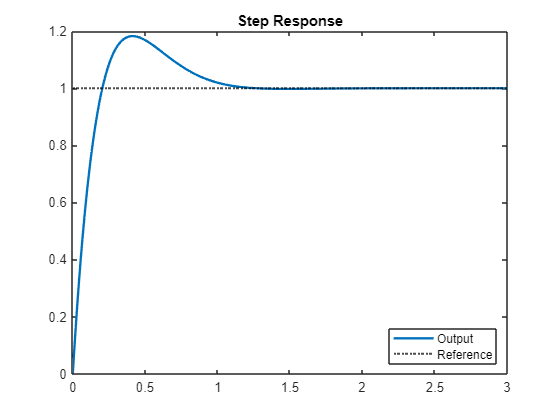

% Control Gains
Kp = 8;
Ki = 25;

% Plant & Controller Definition
G = tf(1,[1 0]);
C = pid(Kp,Ki);

% Closed Loop System Definition
GCL = feedback(C*G,1);

% Time Initialization
dt = 0.01;
t = 0:dt:3;
tLen = length(t);

% Reference
rS = ones(tLen,1); % Step Input
rR = t'.*ones(tLen,1); % Ramp Input

% Initial Conditions & Preallocation
xDot = 0;
x = zeros(tLen,1);
e = zeros(tLen,1);
u = zeros(tLen,1);
eInt = 0;

for i = 1:tLen-1

    % Error
    e(i) = rS(i) - x(i);
    eInt = eInt + e(i)*dt;

    % Controller
    u(i) = Kp*e(i) + Ki*eInt;

    % Plant
    xDot = u(i);
    x(i+1) = x(i) + xDot*dt;

end

figure
plot(t,x)
hold on
yline(rS(1),'k:','LineWidth', 1.5)
title('Step Response')
legend('Output','Reference','Location','southeast')

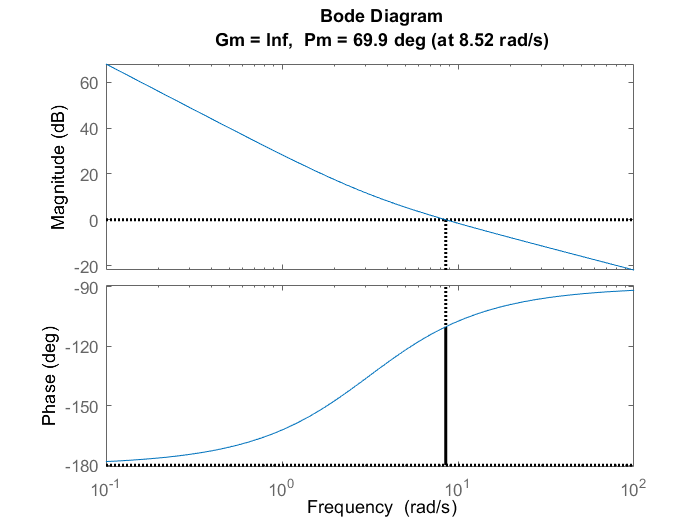


% Gain & Phase Margin
figure
margin(C*G)

- **Part B: **The steady-state error for ramp input is also zero as the system is still Type 2. The ramp response is shown below. 

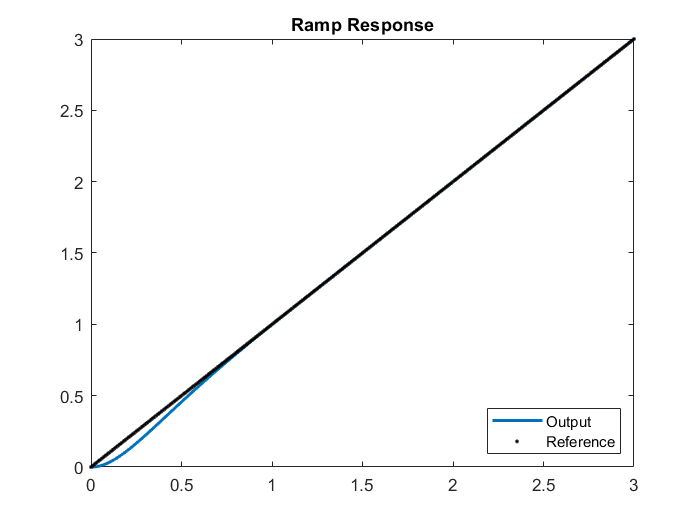

for i = 1:tLen-1

    % Error
    e(i) = rR(i) - x(i);
    eInt = eInt + e(i)*dt;

    % Controller
    u(i) = Kp*e(i) + Ki*eInt;

    % Plant
    xDot = u(i);
    x(i+1) = x(i) + xDot*dt;

end

figure
plot(t,x)
hold on
plot(t,rR,'k.','LineWidth', 1.5)
title('Ramp Response')
legend('Output','Reference','Location','southeast')

- **Part C: **The controller does not need to be redesigned as the initial design was able to track the ramp input.

## Problem 2

Take the sampled 100 Hz sine wave (generate_signal(1)) from the website (Fs = 1 MHz, Ts = 1e-6).

### Find:

- **Part A: **Develop a simple (1 Hz Bandwidth) PLL to track the phase of the signal. Provide plots of phase, phase error, and the estimated signal vs. the actual signal.

- **Part B: **Double the bandwidth and repeat Part A.

- **Part C: **Determine the true frequency and repeat Part A.

- **Part D: **Modify your PLL to work from the unknown frequency and repeat Part A assuming a 10 Hz signal.

### Solution:

- **Part A: **The following plots show the PLL in action using a nominal frequency of 100 Hz and initial phase guess of 0 degrees. The Costas Loop discriminator was used for this PLL the In-Phase only discriminator didn't perform as well. The initial frequency and phase can be tracked but the phase tracking oscillates after signal frequency was changed. However, it can still be determined that the new frequency is 110 Hz.

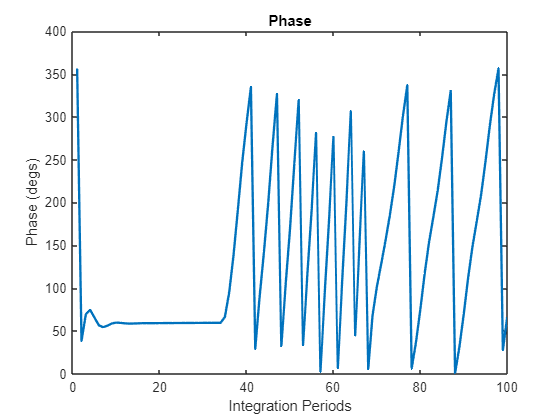

% Sampling Information
fs = 1e6;
ts = 1/fs;

% Generate Signal
sig = generate_signal(1);
sigL = length(sig);
tEnd = sigL/fs;
tSig = 0:ts:(tEnd-ts);

% Time
tInt = 0.01;
pInt = floor(tEnd/tInt);
nSamps = tInt/ts;
t = 0:ts:(tInt-ts);

% PLL
omega0 = 99; % Hz
omega = omega0;
phi0 = 0;
phi = phi0;
eSumInt = 0;
eHat = 0;
bs = 1;
be = int32(nSamps);

% Loop Filter Gains
bW = 1*2*pi;
zeta = 0.9;
Kp = 2*zeta*bW;
Ki = bW^2;

% Log Prellocation
phiL = zeros(pInt,1);
eSumL = zeros(pInt,1);
omegaL = zeros(pInt,1);

for i = 1:pInt

    % Oscillator
    iSig = sin(2*pi*omega*t + phi);
    qSig = cos(2*pi*omega*t + phi);
    phi = phi + rem(2*pi*omega*tInt,2*pi);

    phiL(i) = phi; % Phase Log
    
    % Phase Detector Discriminator
    s = sig(bs:be);
    I = s.*iSig;
    Q = s.*qSig;
    eSum = atan(sum(Q)/sum(I));
    eSumInt = eSumInt + eSum*tInt;

    eSumL(i) = eSum; % Phase Error Log

    % Loop Filter
    eHat = Kp*eSum + Ki*eSumInt;
    omega = omega0 + eHat;

    omegaL(i) = omega; % Frequency Log
    
    % Index Update
    bs = int32(bs + nSamps);
    be = int32(be + nSamps);

end

%% Plotting

figure
plot(wrapTo360(rad2deg(phiL)))
title('Phase')
xlabel('Integration Periods')
ylabel('Phase (degs)')

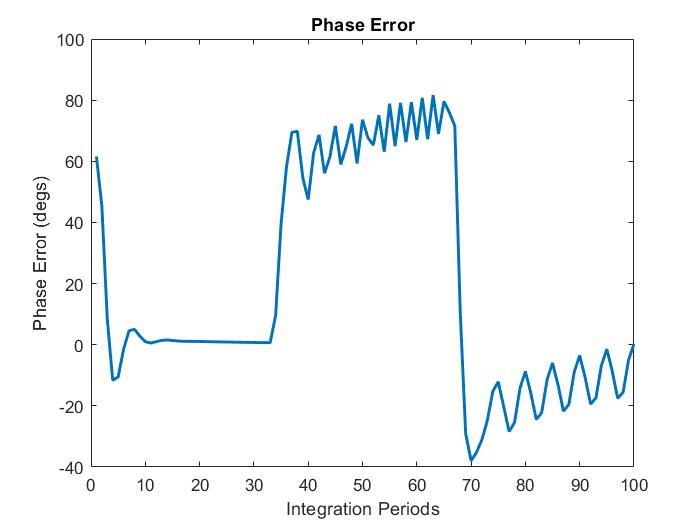


figure
plot(rad2deg(eSumL))
title('Phase Error')
xlabel('Integration Periods')
ylabel('Phase Error (degs)')

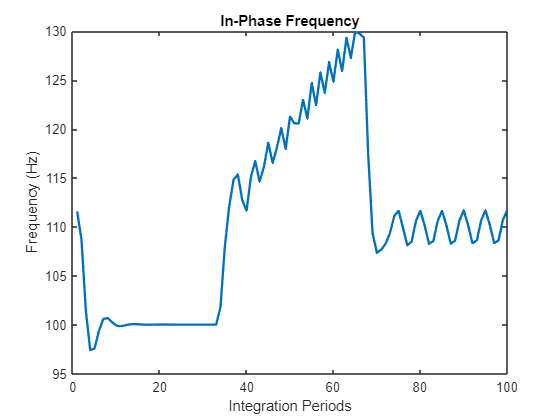


figure
plot(omegaL)
title('In-Phase Frequency')
xlabel('Integration Periods')
ylabel('Frequency (Hz)')

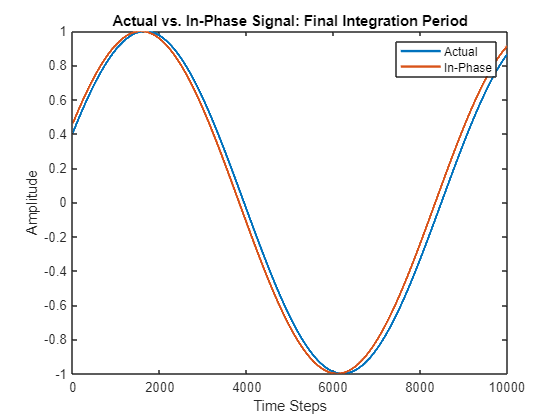


figure
plot(s)
hold on
plot(iSig)
title('Actual vs. In-Phase Signal: Final Integration Period')
xlabel('Time Steps')
ylabel('Amplitude')
legend('Actual','In-Phase')

- **Part B: **The bandwidth of the controller was doubled and the following results for the PLL were produced. It can be seen the phase was still tracked around the same point as in Part A, but the doubling of the bandwidth made the response more underdamped. This can be seen by the continuous overshoot that decays in the first 35 integration periods.

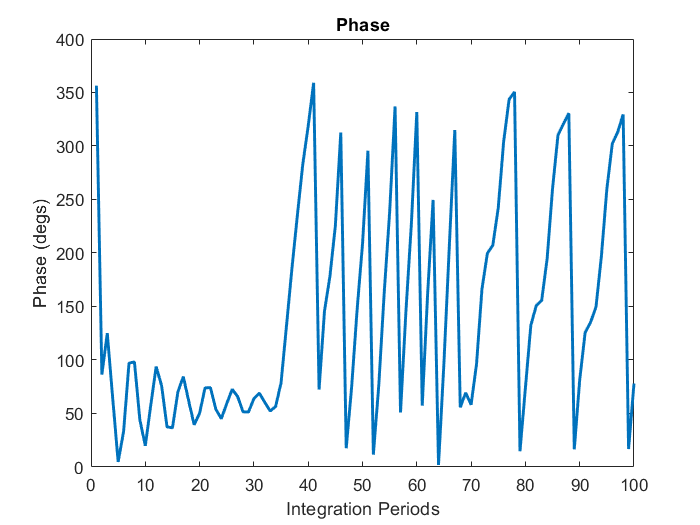

% Sampling Information
fs = 1e6;
ts = 1/fs;

% Generate Signal
sig = generate_signal(1);
sigL = length(sig);
tEnd = sigL/fs;
tSig = 0:ts:(tEnd-ts);

% Time
tInt = 0.01;
pInt = floor(tEnd/tInt);
nSamps = tInt/ts;
t = 0:ts:(tInt-ts);

% PLL
omega0 = 99; % Hz
omega = omega0;
phi0 = 0;
phi = phi0;
eSumInt = 0;
eHat = 0;
bs = 1;
be = int32(nSamps);

% Loop Filter Gains
bW = 2*2*pi;
zeta = 0.9;
Kp = 2*zeta*bW;
Ki = bW^2;

% Log Prellocation
phiL = zeros(pInt,1);
eSumL = zeros(pInt,1);
omegaL = zeros(pInt,1);

for i = 1:pInt

    % Oscillator
    iSig = sin(2*pi*omega*t + phi);
    qSig = cos(2*pi*omega*t + phi);
    phi = phi + rem(2*pi*omega*tInt,2*pi);

    phiL(i) = phi; % Phase Log
    
    % Phase Detector Discriminator
    s = sig(bs:be);
    I = s.*iSig;
    Q = s.*qSig;
    eSum = atan(sum(Q)/sum(I));
    eSumInt = eSumInt + eSum*tInt;

    eSumL(i) = eSum; % Phase Error Log

    % Loop Filter
    eHat = Kp*eSum + Ki*eSumInt;
    omega = omega0 + eHat;

    omegaL(i) = omega; % Frequency Log
    
    % Index Update
    bs = int32(bs + nSamps);
    be = int32(be + nSamps);

end

%% Plotting

figure
plot(wrapTo360(rad2deg(phiL)))
title('Phase')
xlabel('Integration Periods')
ylabel('Phase (degs)')

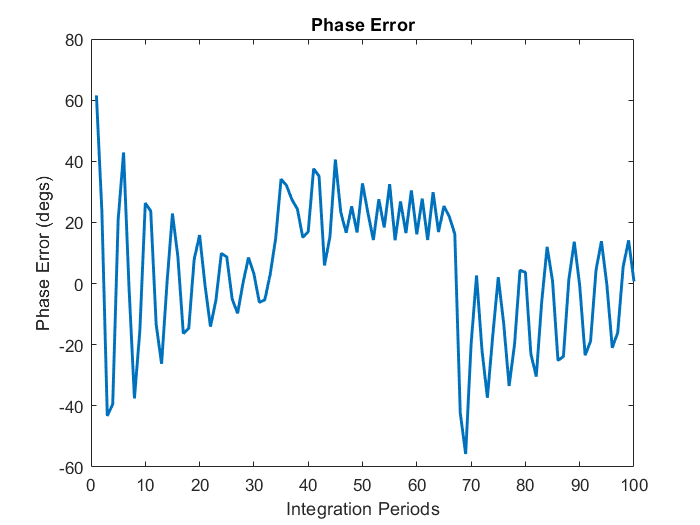


figure
plot(rad2deg(eSumL))
title('Phase Error')
xlabel('Integration Periods')
ylabel('Phase Error (degs)')

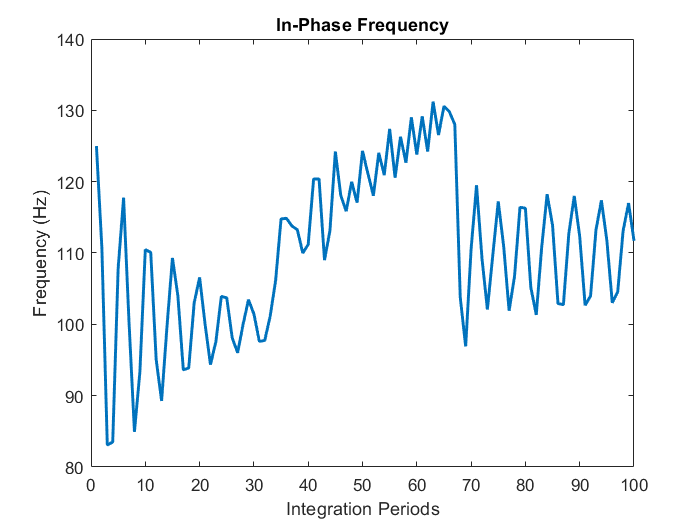


figure
plot(omegaL)
title('In-Phase Frequency')
xlabel('Integration Periods')
ylabel('Frequency (Hz)')

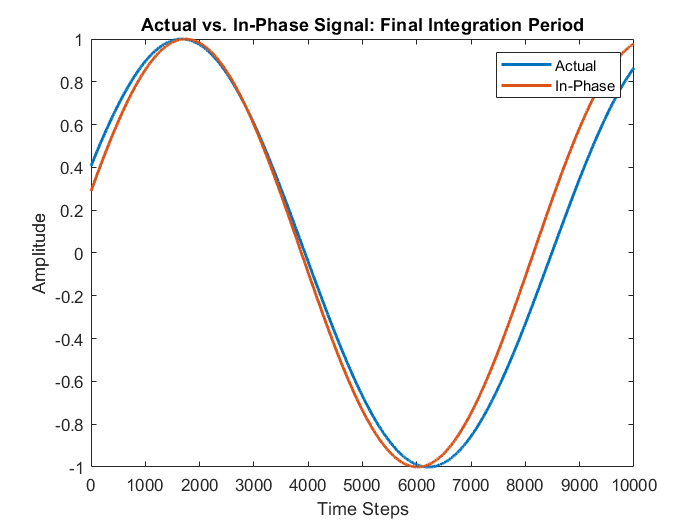


figure
plot(s)
hold on
plot(iSig)
title('Actual vs. In-Phase Signal: Final Integration Period')
xlabel('Time Steps')
ylabel('Amplitude')
legend('Actual','In-Phase')

- **Part C: **The unknown frequency was determined to be 110 Hz. The nominal frequency was then changed to this and the PLL was run again. It can bee seen the inital phase error was worse than in Part A now that the initial frequency differes by 10 Hz. This means the PLL never converges before the frequency is changed. However, it begins to track the 110 Hz part of the signal but still has the same issues with oscillation as in Part A.

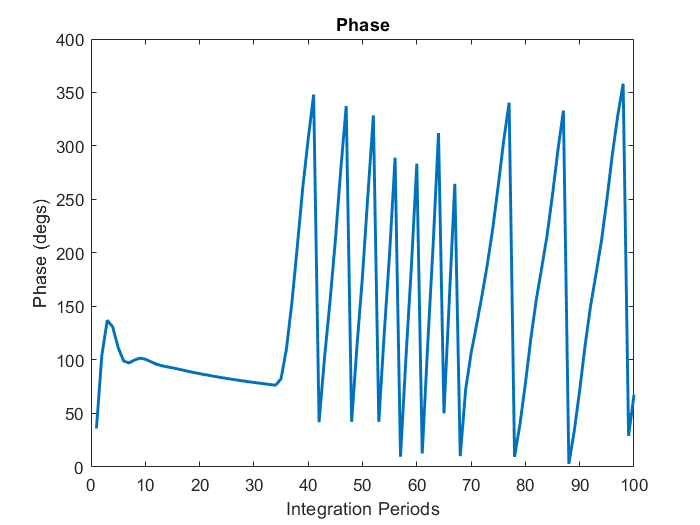

% Sampling Information
fs = 1e6;
ts = 1/fs;

% Generate Signal
sig = generate_signal(1);
sigL = length(sig);
tEnd = sigL/fs;
tSig = 0:ts:(tEnd-ts);

% Time
tInt = 0.01;
pInt = floor(tEnd/tInt);
nSamps = tInt/ts;
t = 0:ts:(tInt-ts);

% PLL
omega0 = 110; % Hz
omega = omega0;
phi0 = 0;
phi = phi0;
eSumInt = 0;
eHat = 0;
bs = 1;
be = int32(nSamps);

% Loop Filter Gains
bW = 1*2*pi;
zeta = 0.9;
Kp = 2*zeta*bW;
Ki = bW^2;

% Log Prellocation
phiL = zeros(pInt,1);
eSumL = zeros(pInt,1);
omegaL = zeros(pInt,1);

for i = 1:pInt

    % Oscillator
    iSig = sin(2*pi*omega*t + phi);
    qSig = cos(2*pi*omega*t + phi);
    phi = phi + rem(2*pi*omega*tInt,2*pi);

    phiL(i) = phi; % Phase Log
    
    % Phase Detector Discriminator
    s = sig(bs:be);
    I = s.*iSig;
    Q = s.*qSig;
    eSum = atan(sum(Q)/sum(I));
    eSumInt = eSumInt + eSum*tInt;

    eSumL(i) = eSum; % Phase Error Log

    % Loop Filter
    eHat = Kp*eSum + Ki*eSumInt;
    omega = omega0 + eHat;

    omegaL(i) = omega; % Frequency Log
    
    % Index Update
    bs = int32(bs + nSamps);
    be = int32(be + nSamps);

end

%% Plotting

figure
plot(wrapTo360(rad2deg(phiL)))
title('Phase')
xlabel('Integration Periods')
ylabel('Phase (degs)')

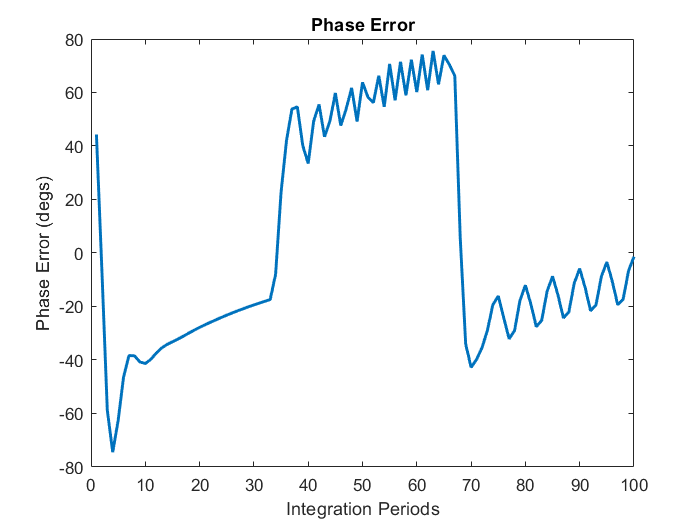


figure
plot(rad2deg(eSumL))
title('Phase Error')
xlabel('Integration Periods')
ylabel('Phase Error (degs)')

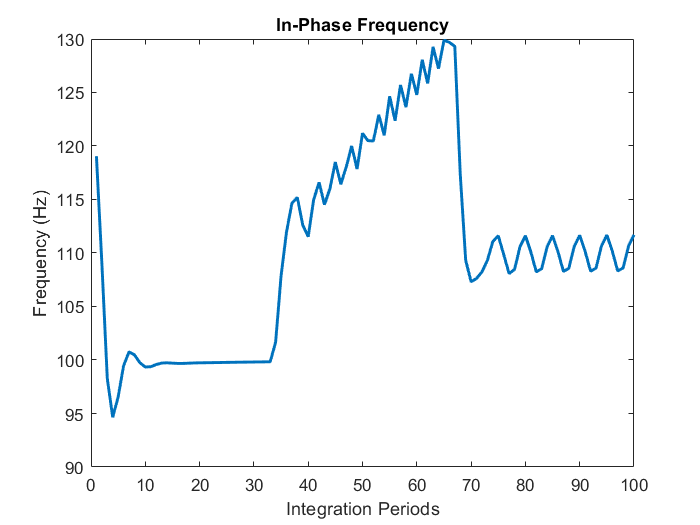


figure
plot(omegaL)
title('In-Phase Frequency')
xlabel('Integration Periods')
ylabel('Frequency (Hz)')

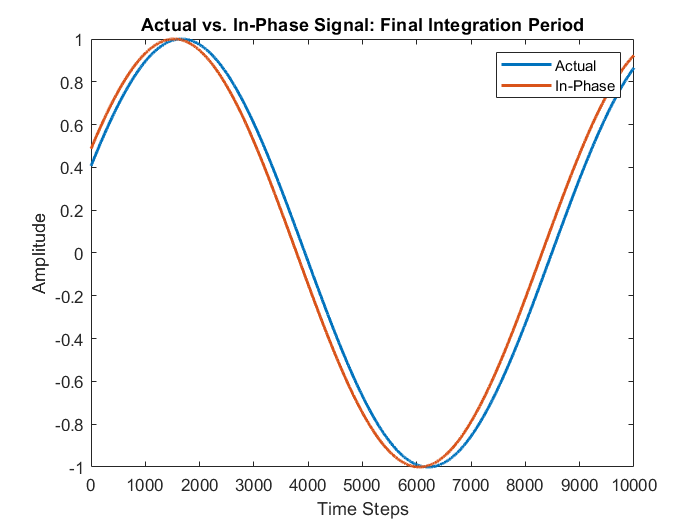


figure
plot(s)
hold on
plot(iSig)
title('Actual vs. In-Phase Signal: Final Integration Period')
xlabel('Time Steps')
ylabel('Amplitude')
legend('Actual','In-Phase')

- **Part D: ** The PLL was then ran again assuming a 10 Hz signal. You can see that it doesn't track at all as the nominal frequency was not even close enough to the lock in region. The poor performance of the PLL is most evident when looking at the frequency plot and signal comparison.

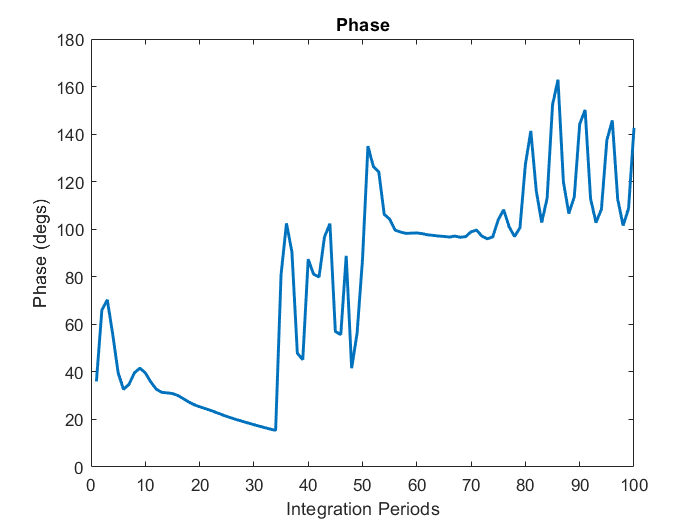

% Sampling Information
fs = 1e6;
ts = 1/fs;

% Generate Signal
sig = generate_signal(1);
sigL = length(sig);
tEnd = sigL/fs;
tSig = 0:ts:(tEnd-ts);

% Time
tInt = 0.01;
pInt = floor(tEnd/tInt);
nSamps = tInt/ts;
t = 0:ts:(tInt-ts);

% PLL
omega0 = 10; % Hz
omega = omega0;
phi0 = 0;
phi = phi0;
eSumInt = 0;
eHat = 0;
bs = 1;
be = int32(nSamps);

% Loop Filter Gains
bW = 1*2*pi;
zeta = 0.9;
Kp = 2*zeta*bW;
Ki = bW^2;

% Log Prellocation
phiL = zeros(pInt,1);
eSumL = zeros(pInt,1);
omegaL = zeros(pInt,1);

for i = 1:pInt

    % Oscillator
    iSig = sin(2*pi*omega*t + phi);
    qSig = cos(2*pi*omega*t + phi);
    phi = phi + rem(2*pi*omega*tInt,2*pi);

    phiL(i) = phi; % Phase Log
    
    % Phase Detector Discriminator
    s = sig(bs:be);
    I = s.*iSig;
    Q = s.*qSig;
    eSum = atan(sum(Q)/sum(I));
    eSumInt = eSumInt + eSum*tInt;

    eSumL(i) = eSum; % Phase Error Log

    % Loop Filter
    eHat = Kp*eSum + Ki*eSumInt;
    omega = omega0 + eHat;

    omegaL(i) = omega; % Frequency Log
    
    % Index Update
    bs = int32(bs + nSamps);
    be = int32(be + nSamps);

end

%% Plotting

figure
plot(wrapTo360(rad2deg(phiL)))
title('Phase')
xlabel('Integration Periods')
ylabel('Phase (degs)')

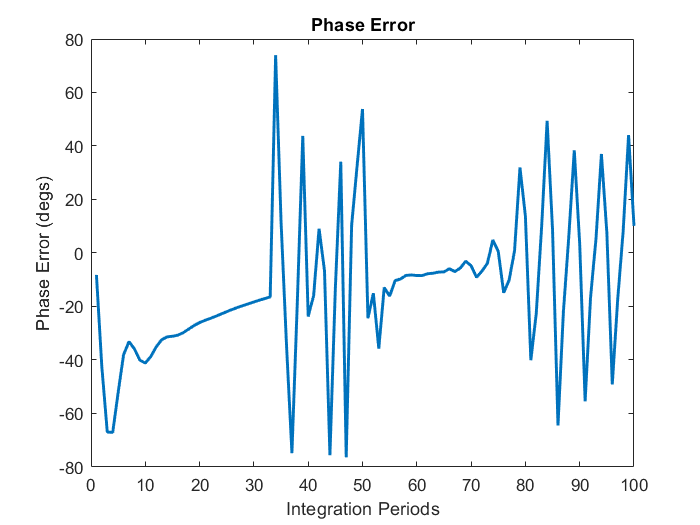


figure
plot(rad2deg(eSumL))
title('Phase Error')
xlabel('Integration Periods')
ylabel('Phase Error (degs)')

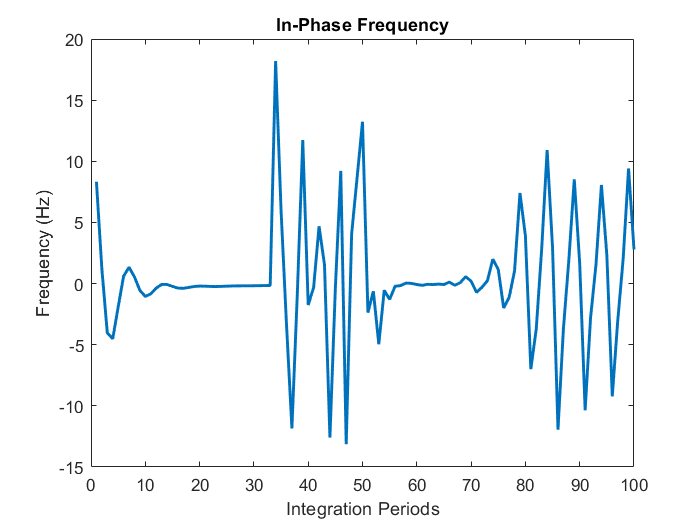


figure
plot(omegaL)
title('In-Phase Frequency')
xlabel('Integration Periods')
ylabel('Frequency (Hz)')

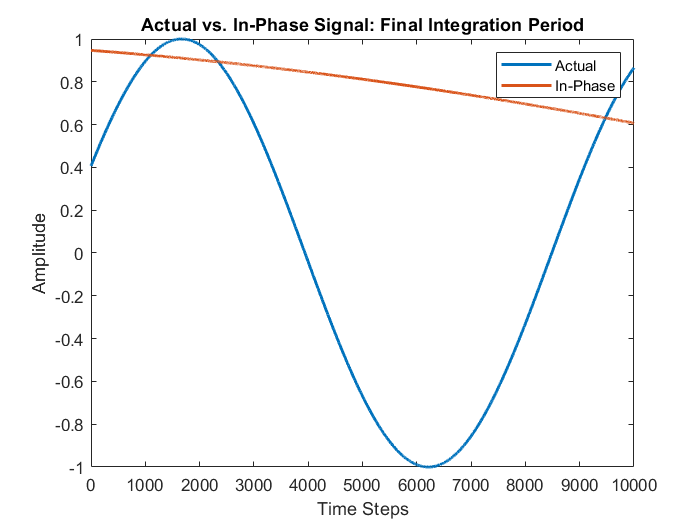


figure
plot(s)
hold on
plot(iSig)
title('Actual vs. In-Phase Signal: Final Integration Period')
xlabel('Time Steps')
ylabel('Amplitude')
legend('Actual','In-Phase')

## Problem 3

Modify your PLL from Problem 2 to operate as a Costas Loop Filter. Take the 88 second data sampled at 1 MHz and decode the data message on the 100 Hz sinusoid using your Costas Loop Filter. The data bits are 1 second wide and are comprised of 8-Bit ASCII characters.

### Solution:

- The same code was used from Problem 2 as I only used the Costas Loop Discriminator. The Loop Filter gains were not changed and the data message was extracted by taking the sum of the In-Phase signal over each integration period. The message was decoded using a function consisting of the code given in the homework problem statement and said "HELLO WORLD". It can be seen in the signal comparison that the In-Phase signal is actually 180 degrees out of phase. This is because the discriminator can either drive the generated signal to in phase or out by 180. This doesn't affect the data message extracted from the sinusoid here as the data bits are 1's and 0's. However, when the data bits in the GPS signal are extracted they need to be double checked as the inlcusion of -1 bits may flip the content of the message.

% Sampling Information
fs = 1e6;
ts = 1/fs;

% Generate Signal
datafile = 'data/sig2.mat';

if isfile(datafile)
    load(datafile)
else
    sig = generate_signal(2);
    save('data/sig2.mat',"sig")
end

sigL = length(sig);
tEnd = sigL/fs;
tSig = 0:ts:(tEnd-ts);

% Time
tInt = 0.01;
pInt = tEnd/tInt;
nSamps = tInt/ts;
t = 0:ts:(tInt-ts);

% PLL
omega0 = 100;
omega = omega0;
phi0 = 0;
phi = phi0;
eSumInt = 0;
eHat = 0;
bs = 1;
be = int32(nSamps);

% Loop Filter Gains
bW = 1*2*pi;
zeta = 0.9;
Kp = 2*zeta*bW;
Ki = bW^2;

% Log Prellocation
phiL = zeros(pInt,1);
eSumL = zeros(pInt,1);
omegaL = zeros(pInt,1);
dataL = zeros(pInt,1);

for i = 1:pInt

    % Oscillator
    iSig = sin(2*pi*omega*t + phi);
    qSig = cos(2*pi*omega*t + phi);
    phi = phi + rem(2*pi*omega*tInt,2*pi);

    phiL(i) = phi; % Phase Log
    
    % Phase Detector Discriminator
    s = sig(bs:be);
    I = s.*iSig;
    Q = s.*qSig;
    eSum = atan(sum(Q)/sum(I));
    eSumInt = eSumInt + eSum*tInt;

    eSumL(i) = eSum; % Phase Error Log
    dataL(i) = sum(I); % Data Message Log

    % Loop Filter
    eHat = Kp*eSum + Ki*eSumInt;
    omega = omega0 + eHat;

    omegaL(i) = omega; % Frequency Log
    
    % Index Update
    bs = int32(bs + nSamps);
    be = int32(be + nSamps);

end

%% Data Decoding
dataL(dataL>0) = 1;
dataL(dataL<0) = 0;
dataL = downsample(dataL,100);

message = binaryVec2Chars(dataL);

The Message Says: HELLO WORLD


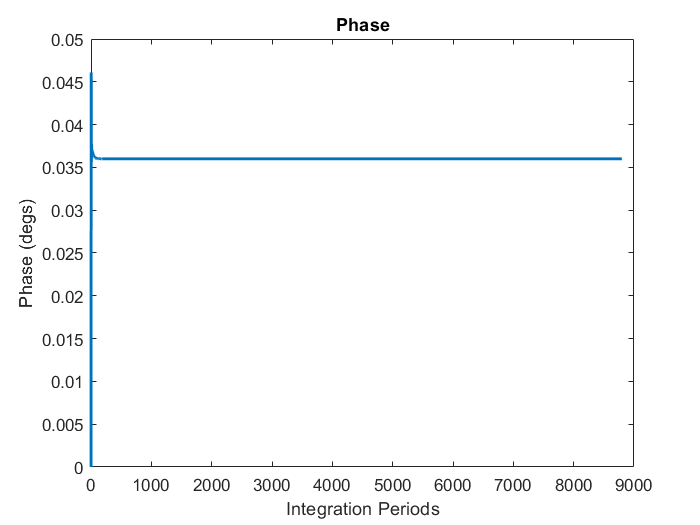


%% Plotting

figure
plot(wrapTo360(rad2deg(phiL)))
title('Phase')
xlabel('Integration Periods')
ylabel('Phase (degs)')

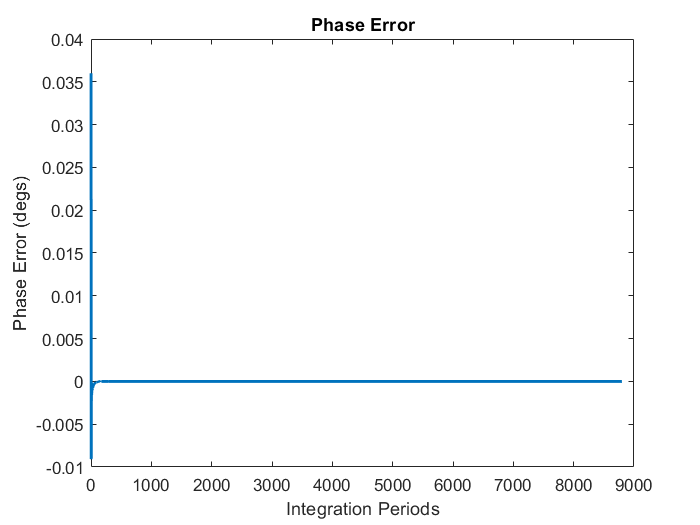


figure
plot(rad2deg(eSumL))
title('Phase Error')
xlabel('Integration Periods')
ylabel('Phase Error (degs)')

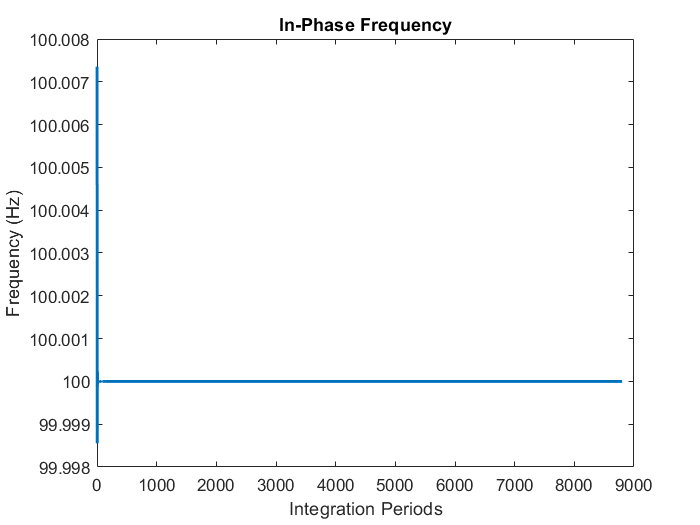


figure
plot(omegaL)
title('In-Phase Frequency')
xlabel('Integration Periods')
ylabel('Frequency (Hz)')

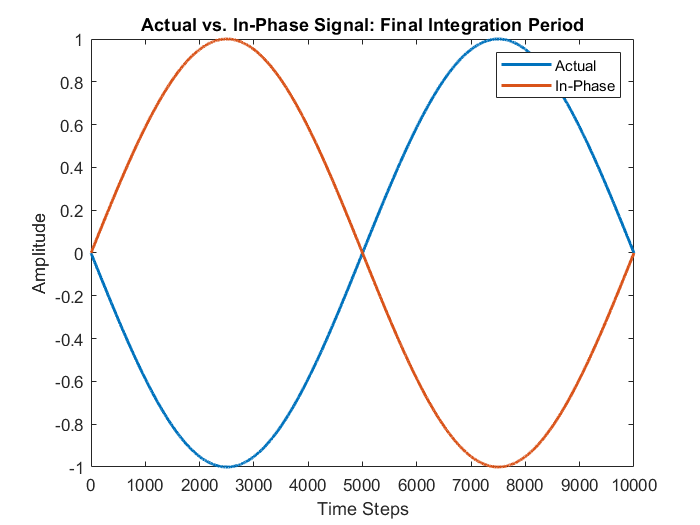


figure
plot(s)
hold on
plot(iSig)
title('Actual vs. In-Phase Signal: Final Integration Period')
xlabel('Time Steps')
ylabel('Amplitude')
legend('Actual','In-Phase')

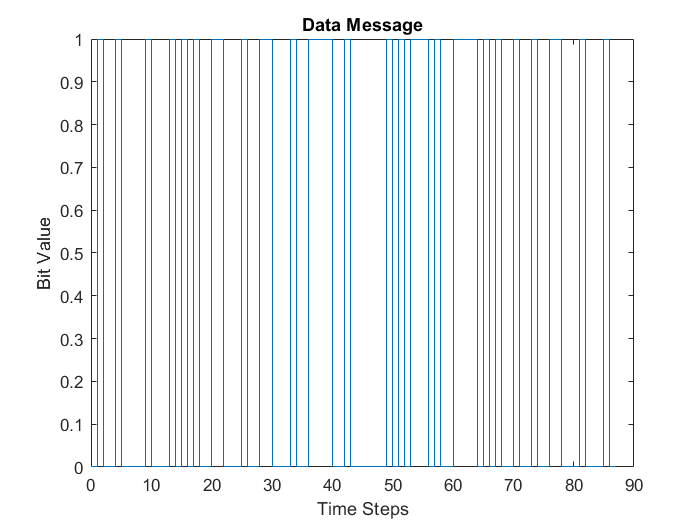


figure
stairs(0:87,dataL)
title('Data Message')
xlabel('Time Steps')
ylabel('Bit Value')

## Problem 6

Take the PRN Code for SV 4 and 7 and upsample it such that there are 16 samples at each chip.

### Find:

- **Part A: **Show the autocorrelation calculation from -5 to +5 chips in 1/16 chip increments.

- **Part B: **Repeat wit noise ($\sigma = 0.2$) added to the non-shifted signal.

### Solution:

- **Part A: **The following code and plots show the result of the autocorrelation of PRN 4 and 7 when they are upsampled. It can be seen the autocorrelation within +/- 1 chip shifted forms a triangle unlike before when the code was not upsampled. This allows for easier tracking as more samples can be used to indicate correlation.

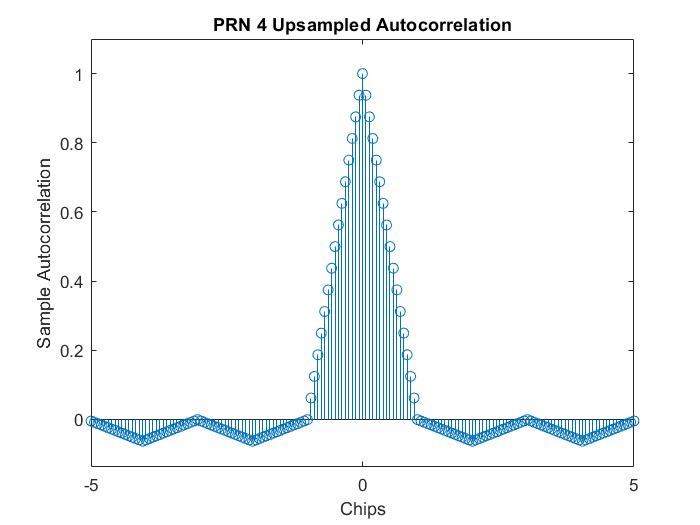

% Generate C/A Code
codeL = 2046;
prn4 = genCA(4,codeL);
prn7 = genCA(7,codeL);

% Upsample C/A Code
upSamp = 16;
prn4 = reshape(repmat(prn4',upSamp,1),1,[]);
prn7 = reshape(repmat(prn7',upSamp,1),1,[]);

% Autocorrelation
numSamp = length(prn4);
r4 = zeros(numSamp,1);
r7 = zeros(numSamp,1);

for i = 1:numSamp
    r4(i) = prn4*circshift(prn4,i)'/numSamp;
    r7(i) = prn7*circshift(prn7,i)'/numSamp;
end

% Plotting
chips = 5;
lLim = (codeL/2)*upSamp - (chips*upSamp) + 1;
rLim = (codeL/2)*upSamp + (chips*upSamp) - 1;

figure
stem(r4)
axis padded
title('PRN 4 Upsampled Autocorrelation')
ylabel('Sample Autocorrelation')
xlabel('Chips')
xlim([lLim rLim])
xticks([lLim (codeL/2)*upSamp rLim])
xticklabels({'-5','0','5'})

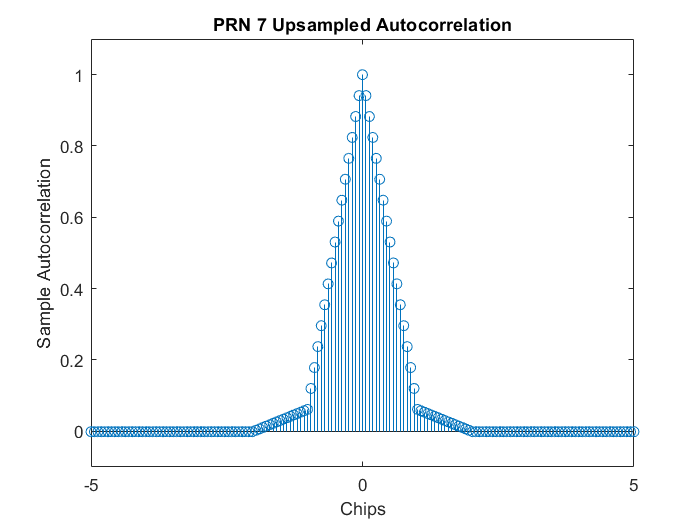


figure
stem(r7)
axis padded
title('PRN 7 Upsampled Autocorrelation')
ylabel('Sample Autocorrelation')
xlabel('Chips')
xlim([lLim rLim])
xticks([lLim (codeL/2)*upSamp rLim])
xticklabels({'-5','0','5'})

- **Part B: **Even with noise added, it can be seen that the autocorrelation is nearly the same indictaing this practice of correlation can be used in a noisy environment such as the one experienced everyday by GPS users.

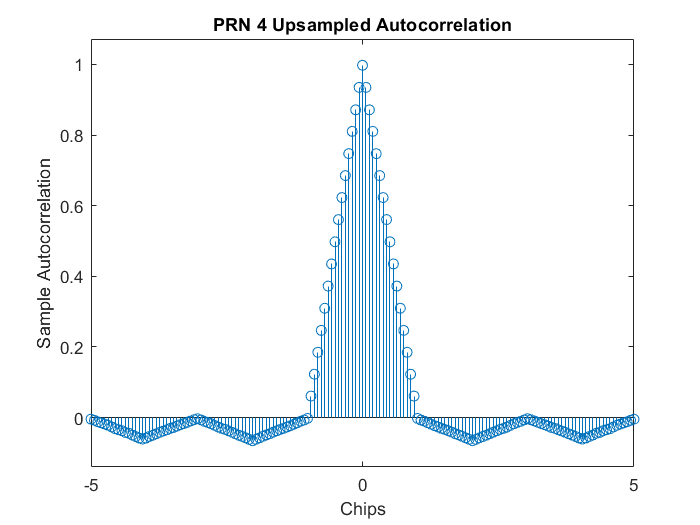

% Noisy PRN
sigma = 0.2;
prn4N = prn4 + sigma*randn(1,numSamp);
prn7N = prn7 + sigma*randn(1,numSamp);

% Autocorrelation
r4N = zeros(numSamp,1);
r7N = zeros(numSamp,1);

for i = 1:numSamp
    r4N(i) = prn4N*circshift(prn4N,i)'/numSamp;
    r7N(i) = prn7N*circshift(prn7N,i)'/numSamp;
end

figure
stem(r4N)
axis padded
title('PRN 4 Upsampled Autocorrelation')
ylabel('Sample Autocorrelation')
xlabel('Chips')
xlim([lLim rLim])
xticks([lLim (codeL/2)*upSamp rLim])
xticklabels({'-5','0','5'})

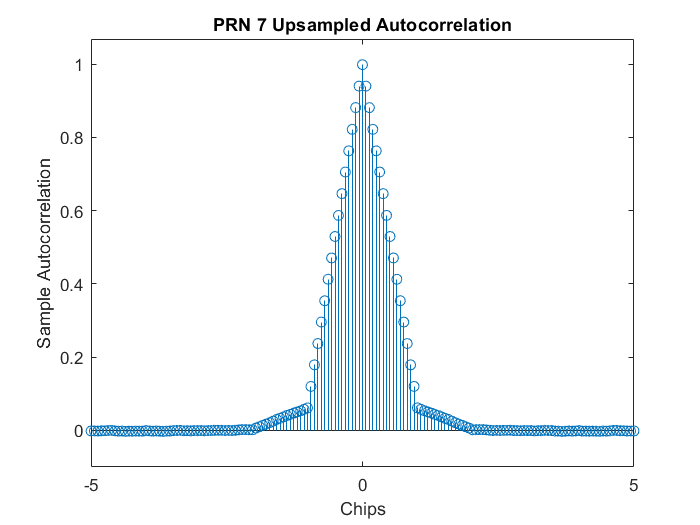


figure
stem(r7N)
axis padded
title('PRN 7 Upsampled Autocorrelation')
ylabel('Sample Autocorrelation')
xlabel('Chips')
xlim([lLim rLim])
xticks([lLim (codeL/2)*upSamp rLim])
xticklabels({'-5','0','5'})

## Problem 7

Write your own acquisition software to acquire a single satellite from the IFEN IF data file. You can write a serial or parallel search algorithim. Provide a plot of the acquisition plane and provide the code phase and doppler results.

### Solution:

- PRN 7 was chosen to be acquired using a serial search algorithim. The following code depicts the process used. It can be seen the PRN can be acquired with 2 2.5ms second integration periods of data stacked together. The code phase was 257 chips and the doppler frequency was in the 4500 Hz bin.

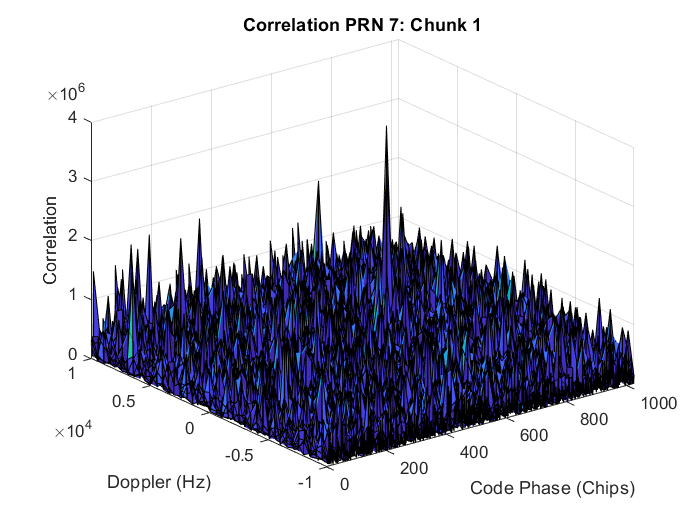

% Data Import
tData = 0.005; % 2 ms of Signal
[sig, sigSamps] = parseIFEN(tData);
s1 = sig(1:sigSamps/2);
s2 = sig((sigSamps/2)+1:end);

% Time Initialization
tInt = tData/2;
fS = 20e6;
tS = 1/fS;
n = 0:tS:tInt-tS;

% Code Initialization
prn = 7;
codeL = 1023;

% Code Upsampling
ca = genCA(prn,codeL);
caU = sample(ca',sigSamps/2,1.023e6,fS,0);
sShift = (sigSamps/2)/codeL;

% Doppler Initialization
fIF = 5000445.88565834; % Intermediate Frequency (Hz)
fBin = 500; % Frequency Bin Size (Hz)
fLim = 10000; % Doppler Frequency Limit (Hz)
fSearch = (fIF-fLim):fBin:(fIF+fLim); % Frequency Search Space
fSearchL = length(fSearch); % Frequency Search Space Length

% Correlation
R1 = zeros(fSearchL,codeL);
R2 = zeros(fSearchL,codeL);

for i = 1:fSearchL
    for j = 1:codeL
        I = s1'.*caU'.*cos(2*pi*fSearch(i)*n);
        Q = s1'.*caU'.*sin(2*pi*fSearch(i)*n);
        R1(i,j) = sum(I)^2 + sum(Q)^2;

        caU = sample(ca',sigSamps/2,1.023e6,fS,j);
    end
end

for i = 1:fSearchL
    for j = 1:codeL
        I = s2'.*caU'.*cos(2*pi*fSearch(i)*n);
        Q = s2'.*caU'.*sin(2*pi*fSearch(i)*n);
        R2(i,j) = sum(I)^2 + sum(Q)^2;

        caU = sample(ca',sigSamps/2,1.023e6,fS,j);
    end
end

%% Plotting
[X,Y] = meshgrid(1:codeL, -fLim:fBin:fLim);

figure
surf(X,Y,R1)
title('Correlation PRN 7: Chunk 1')
xlabel('Code Phase (Chips)')
ylabel('Doppler (Hz)')
zlabel('Correlation')
xlim([0 codeL])

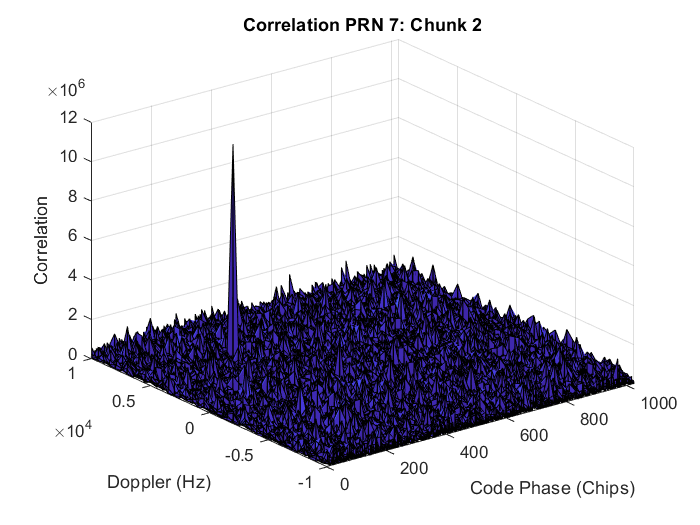


figure
surf(X,Y,R2)
title('Correlation PRN 7: Chunk 2')
xlabel('Code Phase (Chips)')
ylabel('Doppler (Hz)')
zlabel('Correlation')
xlim([0 codeL])

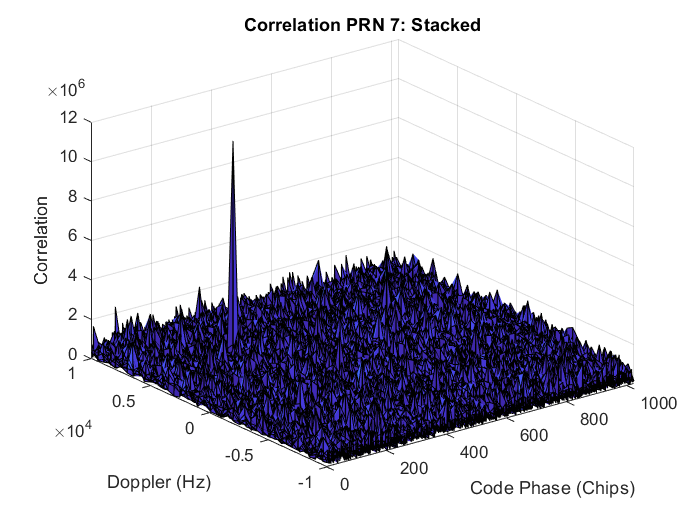


figure
surf(X,Y,R1+R2)
title('Correlation PRN 7: Stacked')
xlabel('Code Phase (Chips)')
ylabel('Doppler (Hz)')
zlabel('Correlation')
xlim([0 codeL])